## Sistema de Control para Quadcóptero

Este archivo contiene las variables y condiciones iniciales empleadas para el sistema de control de un quadcóptero.

Limpiar el workspace.

clc, clear, close all;

Definir las constantes generales.

- Constante de gravedad en la Tierra $g=9.81\;\mathrm{m/s^2}$.

- Masa del dron $m = 0.500\;\mathrm{g}$.

- Constante de elevación $k=2.98\times10^{-6}\;\mathrm{kg\;m}$.

- Distancia del motor al centro del dron $l=0.250\;\mathrm{m}$.

- Constante de arrastre $b=1.14\times10^{-7}\;\mathrm{kg\;m}$.

- Momento de inercia del motor $I=3.36\times10^{-5}\;\mathrm{kg\;m^2}$.

- Momento de inercia en $x$ $I_{xx}=4.86\times10^{-3}\;\mathrm{kg\;m^2}$.

- Momento de inercia en $y$ $I_{yy}=4.86\times10^{-3}\;\mathrm{kg\;m^2}$.

- Momento de inercia en $z$ $I_{zz}=8.80\times10^{-3}\;\mathrm{kg\;m^2}$.

g = 9.81;
m = 0.500;
k = 2.98e-6;
l = 0.250;
b = 1.14e-7;
Ir = 3.36e-5;
Ixx = 4.86e-3;
Iyy = 4.86e-3;
Izz = 8.80e-3;

Definir la configuración inicial.

- Roll inicial $\phi_0$ en $\mathrm{rad}$.

- Pitch inicial $\theta_0$ en $\mathrm{rad}$.

- Yaw inicial $\psi_0$ en $\mathrm{rad}$.

- Altura inicial $z_0$ en $\mathrm{m}$.

roll_0 = -0.1;
pitch_0 = -0.9;
yaw_0 = -3;
z_0 = 0;

Definir la configuración deseada.

- Roll deseado $\phi_d$ en $\mathrm{rad}$.

- Pitch deseado $\theta_d$ en $\mathrm{rad}$.

- Yaw deseado $\psi_d$ en $\mathrm{rad}$.

- Altura deseada $z_d$ en $\mathrm{m}$.

roll_d = -0.3;
pitch_d = 0;
yaw_d = -pi;
z_d = 5;

Correr la simulación de Simulink.

out = sim("drone_control_model");

Graficar la posición lineal del dron en el espacio $$xyz$$.

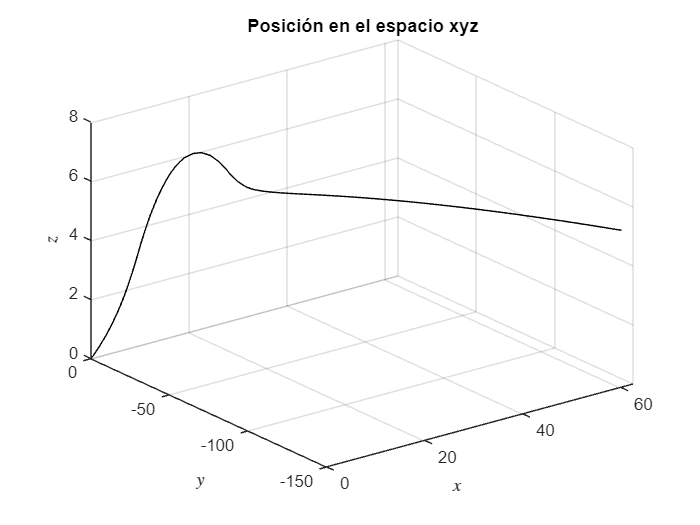

figure('Name', 'Posición lineal', 'NumberTitle','off')
plot3(out.x, out.y, out.z, 'black')
xlabel('$x$', 'interpreter', 'latex')
ylabel('$y$', 'interpreter', 'latex')
zlabel('$z$', 'interpreter', 'latex')
title('Posición en el espacio xyz')
grid on